num = 2;
objective_func = @Akley;


Single objective optimization:
2 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverheuristic
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1             1000           3.074           17.07        0
    2             1475          0.9364           12.38        0
    3             1950          0.4247           8.096        0
    4             2425         0.05613            5.27        0
    5             2900         0.05613             3.4        1
    6             3375         0.02569           2.068        0
    7             3850          0.0134            1.37        0
    8             4325        0.006628           1.065        0
    9             4800         0.00126          0.9826        0
   10             5275        0.001118          0.9232        0
   11      

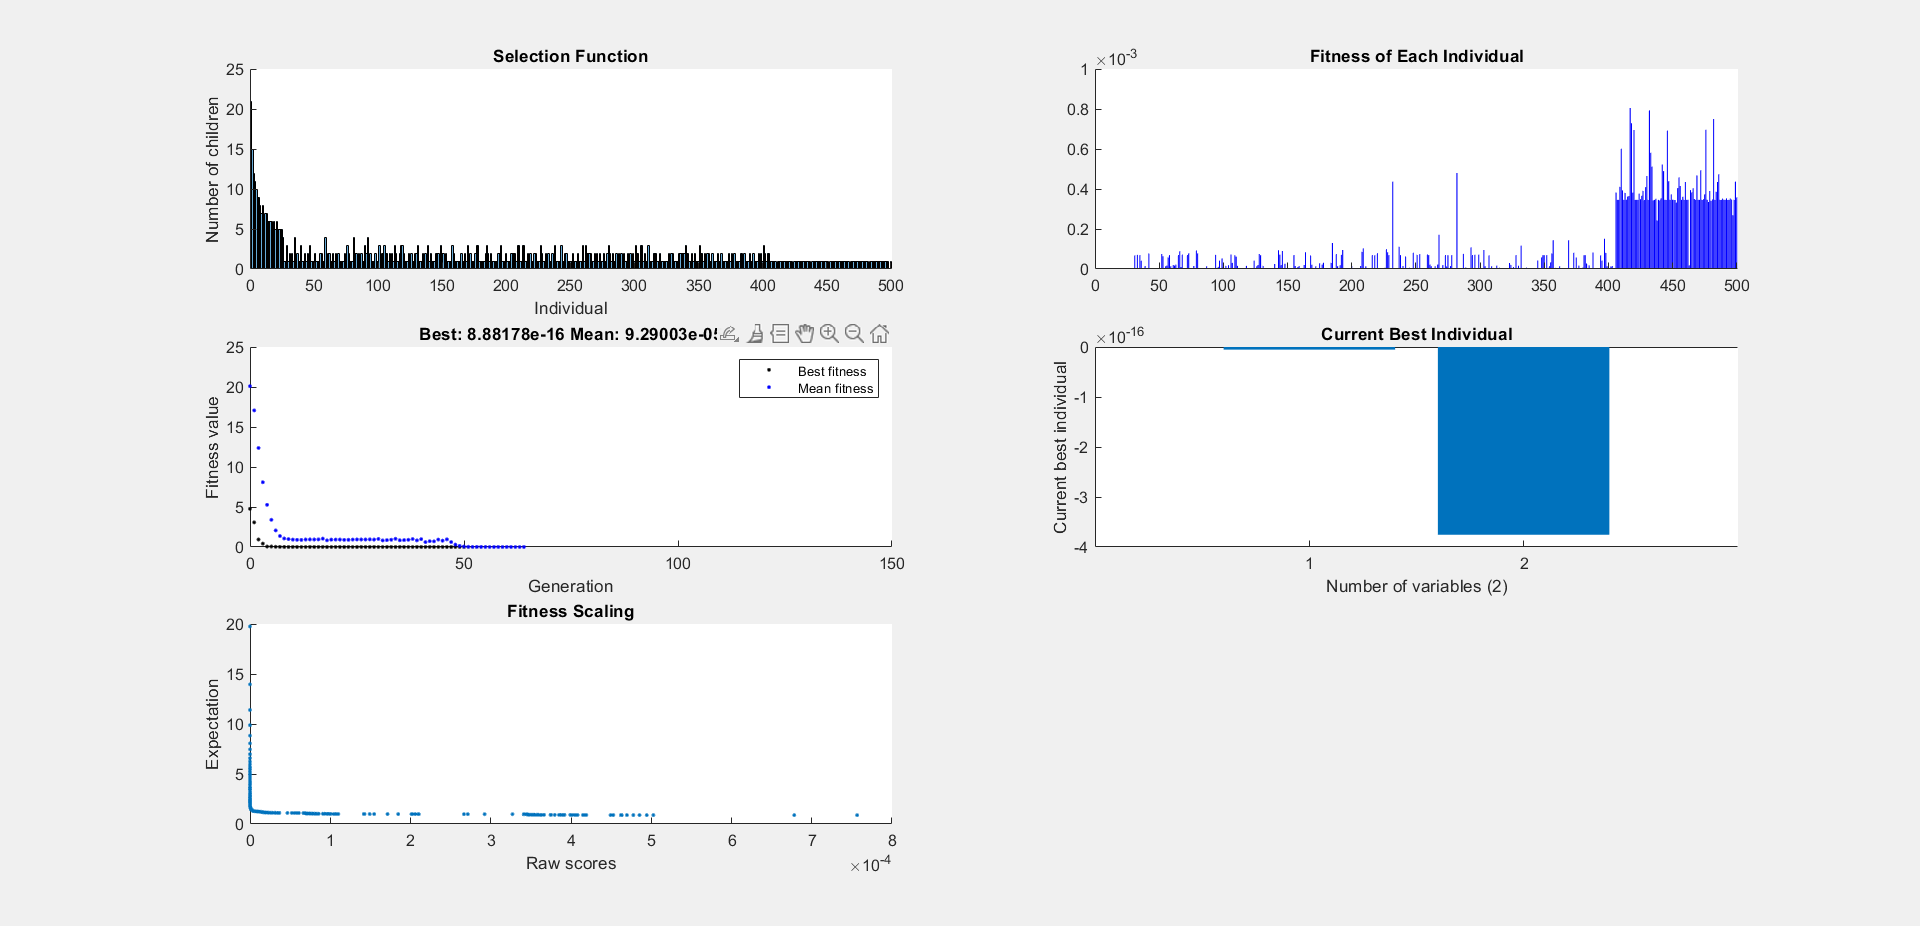

% Set nondefault solver options
options = optimoptions("ga","CrossoverFcn","crossoverheuristic",...
    "MutationFcn","mutationadaptfeasible","MaxGenerations",150,...
    "PopulationSize",500,"Display","iter","PlotFcn",["gaplotselection",...
    "gaplotscores","gaplotbestf","gaplotbestindiv","gaplotexpectation"]);

% Solve
[solution4,objectiveValue4] = ga(@Akley,num,[],[],[],[],repmat(-32,num,1),...
    repmat(32,num,1),[],[],options);


% Clear variables
clearvars options

disp(objectiveValue4);

   8.8818e-16



disp(solution4);

   1.0e-15 *

   -0.0053   -0.3754

